# Hemisphere Rolling

clear

% Principal parameters of shell (body B):
syms R_g R_Bo I_p I_s m_B real positive
r_gb = [0;0;-R_g]; % basis B
I_Bg = diag([I_p,I_p,I_s]); % basis B

syms beta(t) omega(t) [3,1]
% rotation matrix from inertial basis to body basis:
P_IB = spinmat([1,2,3],beta.');
omega_BI = omega; % basis B
alpha_BI = diff(omega_BI,t); % basis B
% we will eventually relate the time derivatives of the euler angles to the
% angluar velocity components, but for now that is unneccessary
syms r_bo(t) [3,1] % q = [x;y;z] % basis I

syms g real positive

## Dynamics:

% LMB:
syms F_p [3,1] real % basis I
F_g = [0;0;-m_B*g]; % basis I
a_gb = cross(omega_BI,cross(omega_BI,r_gb)) + cross(alpha_BI,r_gb); % basis B
F_B = F_p + F_g == m_B*(P_IB*a_gb+diff(r_bo,t,t));

% AMB:
r_pb = [0;0;-R_Bo]; % basis I
r_pg = P_IB.'*r_pb - r_gb; % basis B
M_Bg = cross(r_pg,P_IB.'*F_p) == I_Bg*alpha_BI + cross(omega_BI,I_Bg*omega_BI);

% no slip constraint: v_po = v_pg + v_go = 0
v_po = cross(P_IB*omega_BI,r_pb) + diff(r_bo,t) == 0;
a_po = diff(v_po,t);

## Convert from functions to variables:

syms omega_dot_ q q_dot_ q_ddot_ [3,1] real
eqns = subs([F_B;M_Bg;a_po],[diff(r_bo,t,t);diff(omega,t)], [q_ddot_;omega_dot_]);
eqns = subs(eqns,diff([r_bo;beta],t), [q_dot_;[sec(beta2),0,0;0,1,0;-tan(beta2),0,1]*spinmat(3,beta3)*omega]);
eqns = subs(eqns,[r_bo;beta;omega], [q;sym('beta',[3,1]);sym('omega',[3,1])]);

[A,f] = equationsToMatrix(simplify(eqns),[q_ddot_;omega_dot_;F_p]);

vars = [q; sym('beta',[3,1]); q_dot_; sym('omega',[3,1])];

%clear up some RAM
clearvars -except A f vars

## Substitute in Values:

% dimensional parameters:
R_Bo = 1;
R_Bi = 0.9;
m_B = 15;
theta_b = pi; % angular extent of shell
g = 9.8;

%initial conditions:
r_bo0 = [0;0;R_Bo];
beta0 = [1;0;0];
omega0= [1;0;1];

%simulation duration:
tf = 5;

% don't adjust these:
P_IB0 = spinmat([1,2,3],beta0');
v_bo0 = cross(P_IB0*omega0,[0;0;R_Bo]);

R_g = (3/8)*((R_Bo^4-R_Bi^4)/(R_Bo^3-R_Bi^3))*(1+cos(theta_b/2));
I_p = m_B*((R_Bo^5-R_Bi^5)/(R_Bo^3-R_Bi^3))*(1/10)*(4+cos(theta_b/2)*(1+cos(theta_b/2))) - m_B*R_g^2;
I_s = m_B*((R_Bo^5-R_Bi^5)/(R_Bo^3-R_Bi^3))*(1/5 )*(2-cos(theta_b/2)*(1+cos(theta_b/2)));

## Integrate:

hA = matlabFunction(subs(A),'Vars',{vars});
hf = matlabFunction(subs(f),'Vars',{vars});
% beta dot in terms of beta and omega
hw = @(b,w) [sec(b(2)),0,0;0,1,0;-tan(b(2)),0,1]*spinmat(3,b(3))*w;

function z_dot = EOM(~,z,hA,hf,hw)
beta_dot = hw(z(4:6),z(10:12));
u = hA(z)\hf(z);
z_dot = [z(7:9);
         beta_dot;
         u(1:6)];
end

[t,z] = ode45(@(t,z)EOM(t,z,hA,hf,hw), linspace(0,tf,30*tf),[r_bo0;beta0;v_bo0;omega0]);
z=z';

## Animate:

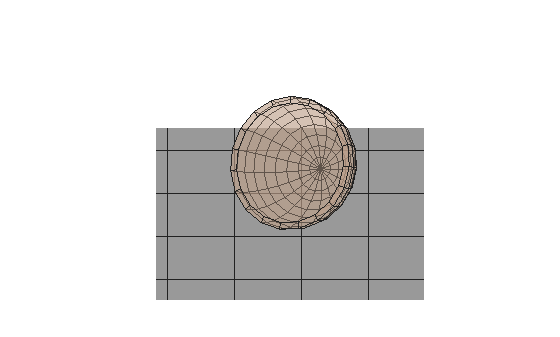

r_bo = @(i) z(1:3,i);
P_IB = @(i) spinmat([1,2,3],z([4,5,6],i)');

figure(1)
clf
hold on
view([0 40])
[a,b] = meshgrid((-10:10)*R_Bo);
surf(a,b,zeros(size(a)),'FaceColor',[1,1,1]*0.6)
% make shell:
shell = hgtransform;
buildShell(shell,R_Bi,R_Bo,theta_b,[.75,.63,.54],0.4)
axis equal off
axis manual
for i = 1:length(t)
    set(shell,'Matrix',[P_IB(i),r_bo(i);[0,0,0,1]])
    axis([z(1,i)+[-1,1]*2*R_Bo,z(2,i)+[-1,1]*2*R_Bo,[0,1]*2*R_Bo])
    drawnow
end

## Check Conservation of Energy:

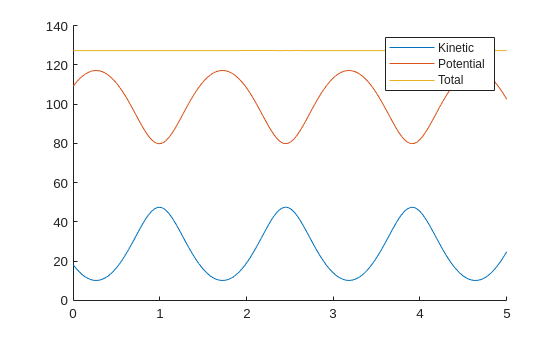

r_gb = [0;0;-R_g]; % basis B
I_Bg = diag([I_p,I_p,I_s]); % basis B
v_go = @(i) (cross(z(10:12,i),r_gb) + P_IB(i)'*z(7:9,i)); % basis B
T_B = arrayfun(@(i) (1/2)*z(10:12,i)'*I_Bg*z(10:12,i) + (1/2)*m_B*v_go(i)'*v_go(i),1:length(t));
V_B = arrayfun(@(i) [0,0,m_B*g]*(P_IB(i)*r_gb+z(1:3,i)),1:length(t));


figure(2)
clf
hold on
plot(t,T_B,'DisplayName','Kinetic')
plot(t,V_B,'DisplayName','Potential')
plot(t,T_B+V_B,'DisplayName','Total')
legend

## Helper Functions:

function buildShell(hg, R_in,R_out,angle,colr,alpha)
theta = linspace(pi-angle/2,pi,round(10*angle/pi))'; phi = linspace(0,2*pi,20);
x = cos(phi).*sin(theta); y = sin(phi).*sin(theta); z = cos(theta)*ones(size(phi));
surf(R_out*x,R_out*y,R_out*z,'FaceColor',colr,'FaceAlpha',alpha,'Parent',hg)
if angle<2*pi && R_in>0
    surf(R_in*x, R_in*y, R_in*z,'FaceColor',colr,'EdgeColor','none','FaceAlpha',alpha,'Parent',hg)
    r = [R_in;R_out].*ones(size(phi));
    theta = pi-angle/2;
    x = r.*cos(phi)*sin(theta); y = r.*sin(phi)*sin(theta); z = r.*cos(theta);
    surf(x,y,z,'FaceColor',colr,'FaceAlpha',alpha,'Parent',hg)
end
end